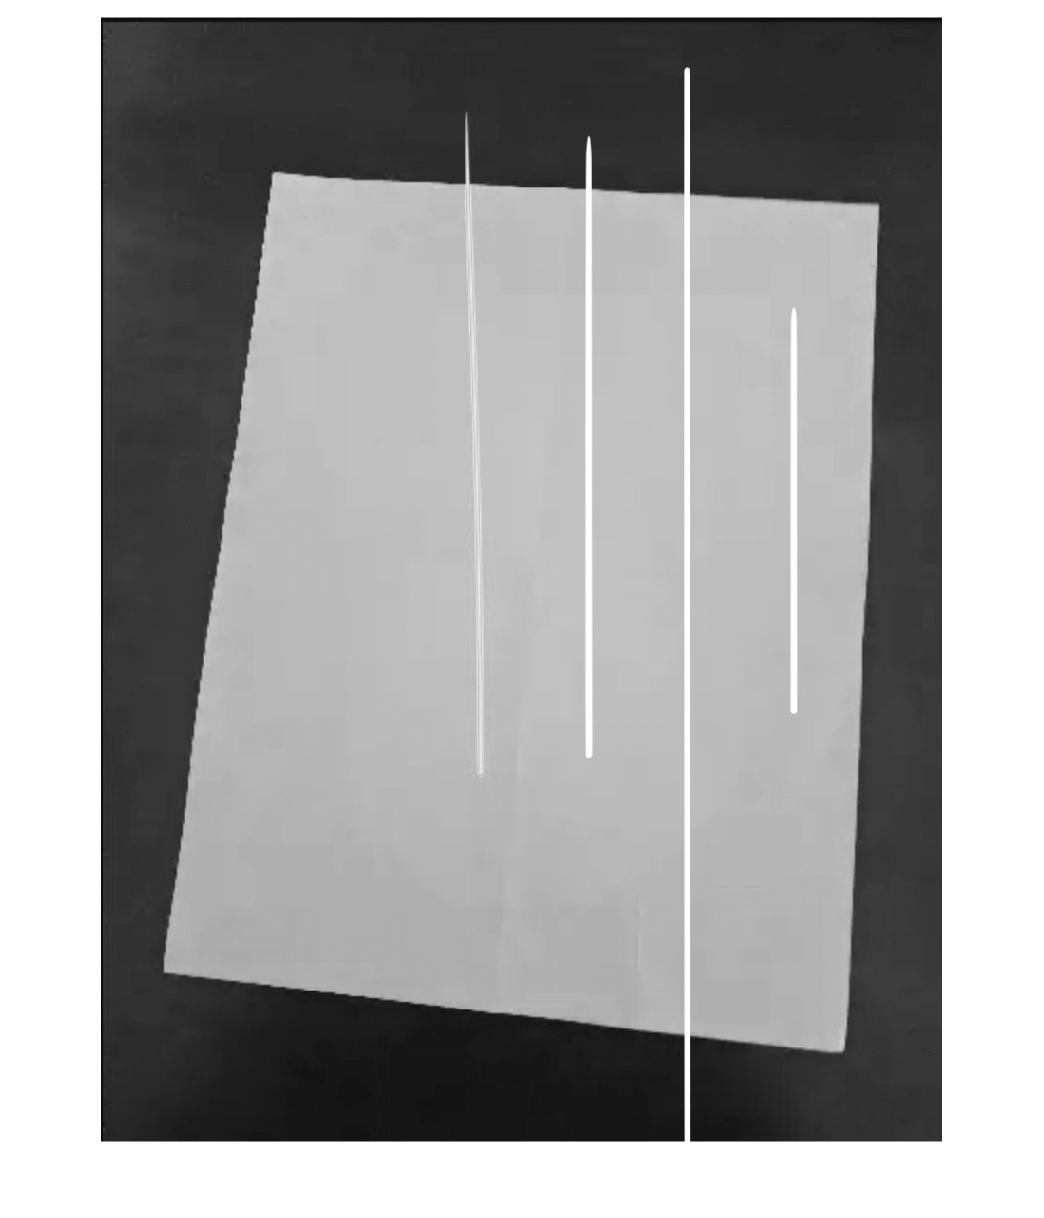

clear
grayImage= imread("gray_line.jpg");
imshow(grayImage);

img = cat(3, grayImage, grayImage, grayImage);


[r,c,k]= size(img);

mask = zeros(r,c);

% After checking R G B of each line, every line has values of RGB more than
% 205, so I I remove the pixel with RGB more than 205.s
for i = 1:r
    for j = 1:c
        
        if img(i,j,1)>205
            if img(i,j,2)>205
                if img(i,j,3)>205
                   mask(i,j)=1;
                end
            end
            
        end
    end
end


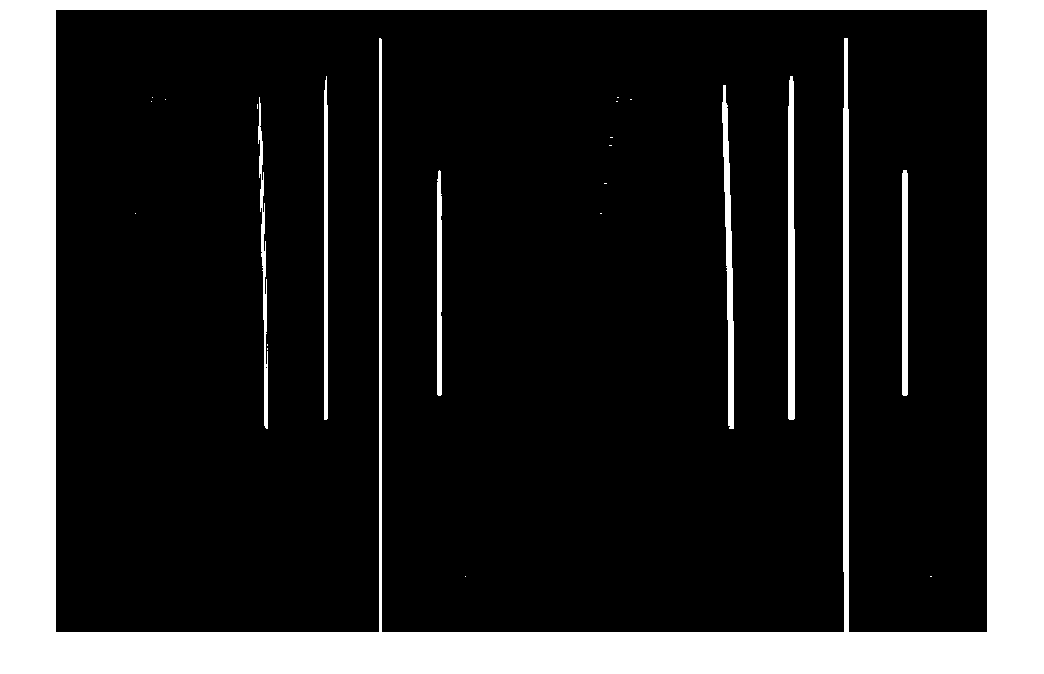


se = strel('line',5,0);
e_m = imdilate(mask,se);

imshowpair(mask,e_m,"montage")

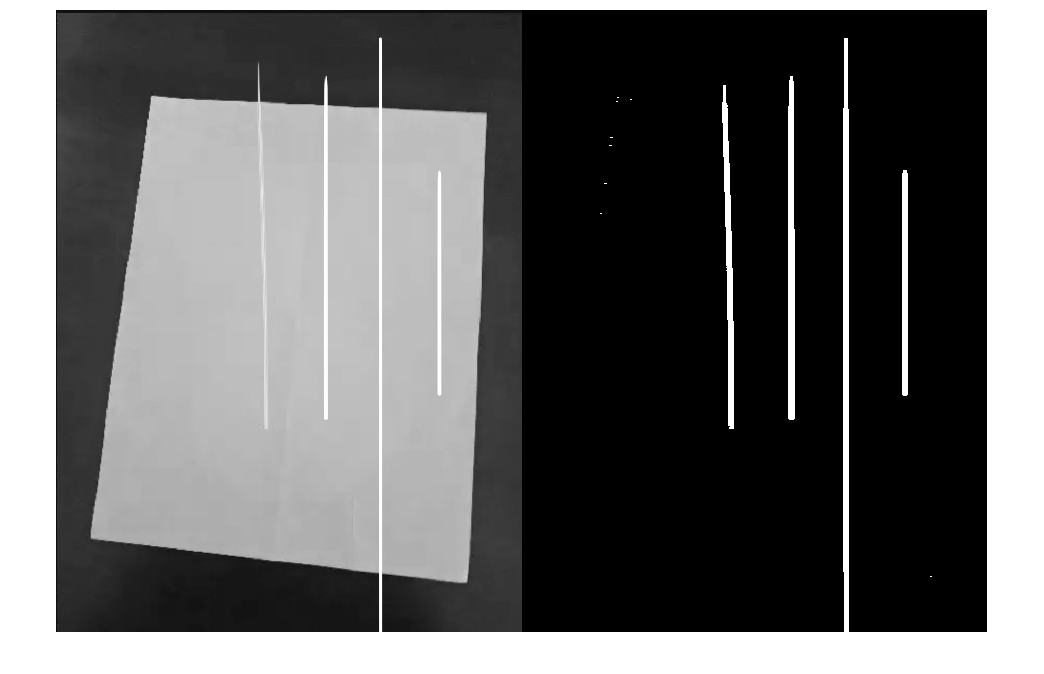

imshowpair(img,e_m,"montage")

mask_bl = imgaussfilt(double(mask), 1);
mask_bl = logical(mask_bl);

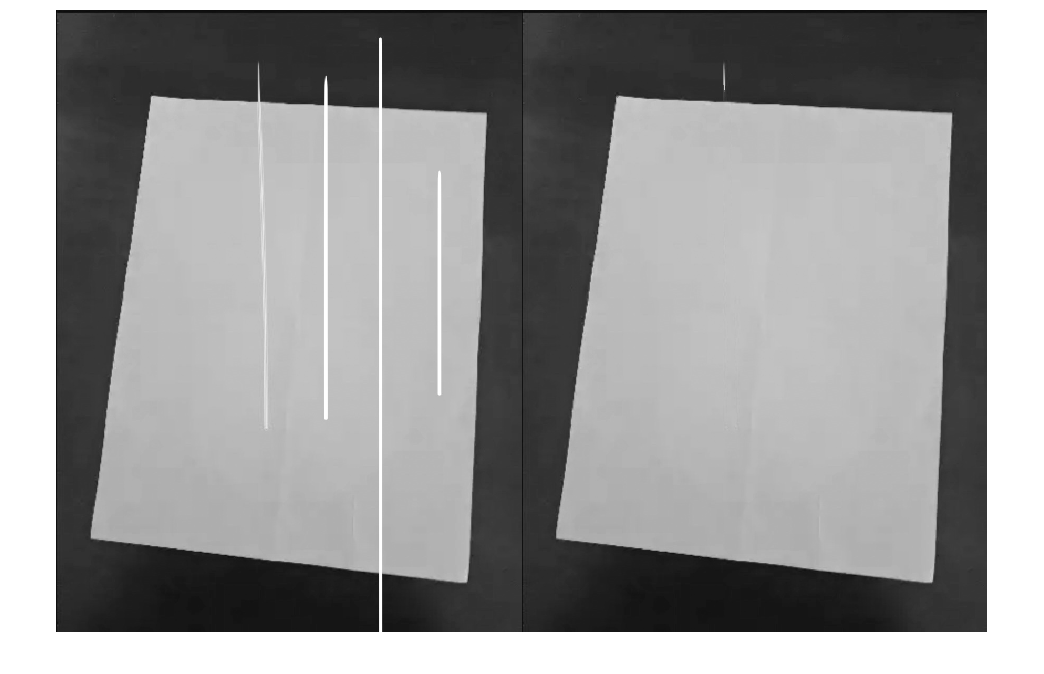

removeLineImg = inpaintCoherent(img,mask_bl);
% Before vs After
imshowpair(img,removeLineImg,"montage");

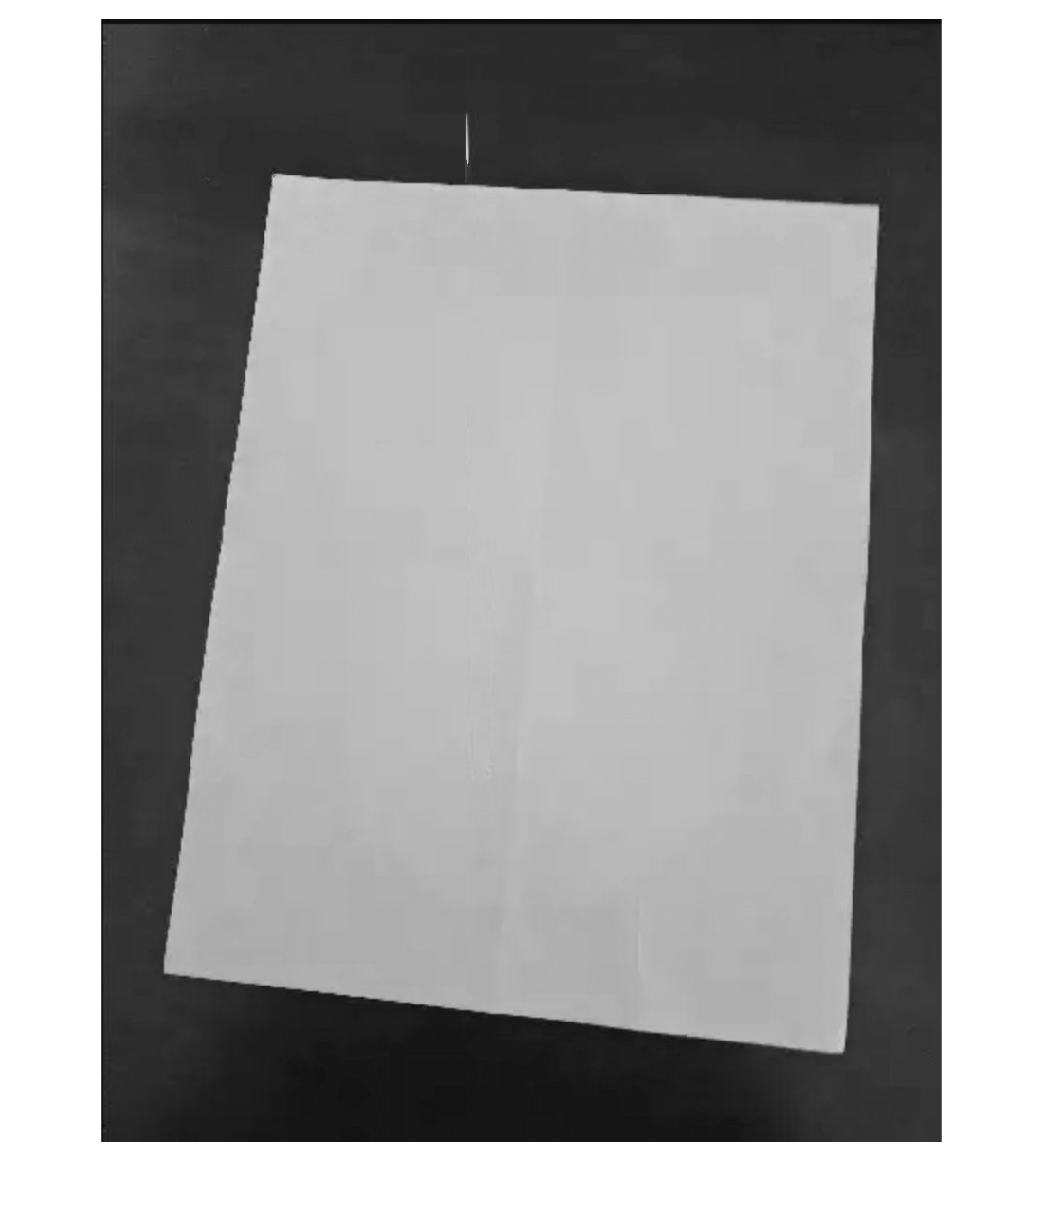

imshow(removeLineImg);

imwrite(removeLineImg,'withoutline.jpg')